G = tf(1,[1 1])

G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.




%help c2d
Gzi = c2d(G,.01,'impulse')

Gzi =
 
   0.01 z
  --------
  z - 0.99
 
Sample time: 0.01 seconds
Discrete-time transfer function.



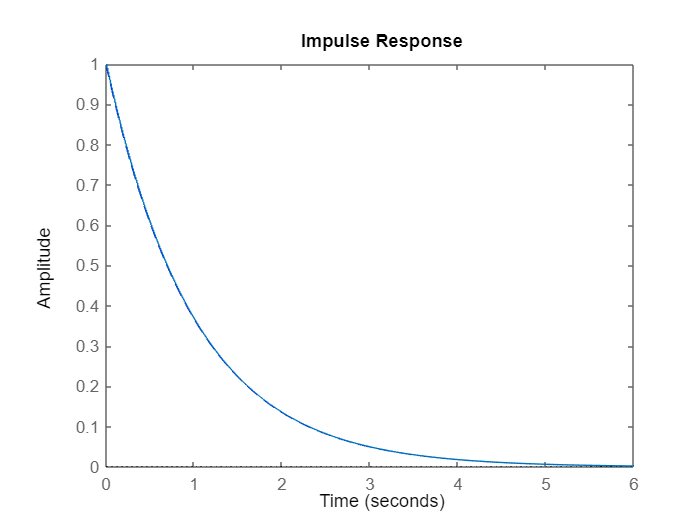


impulse(G,'--', Gzi)

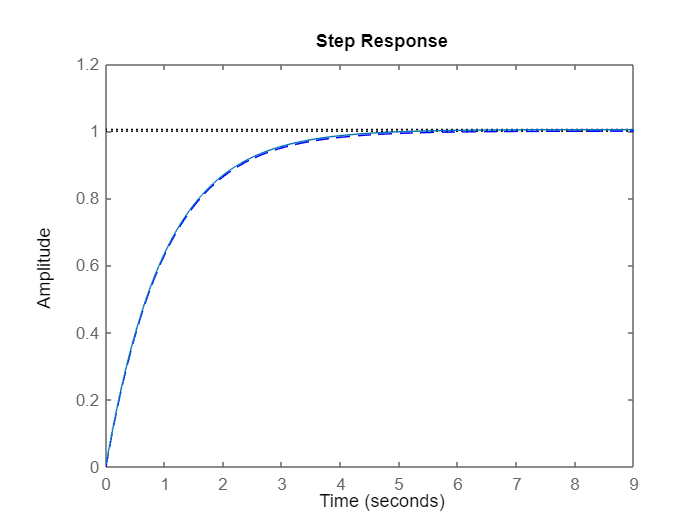

step(G,'--', Gzi)

faktor = 0.1/(1-exp(-.1))

faktor = 1.0508

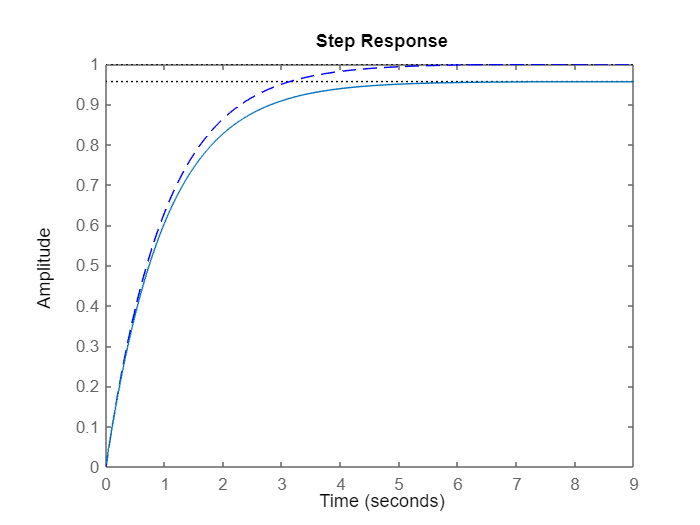

step(G,'--', Gzi/faktor)

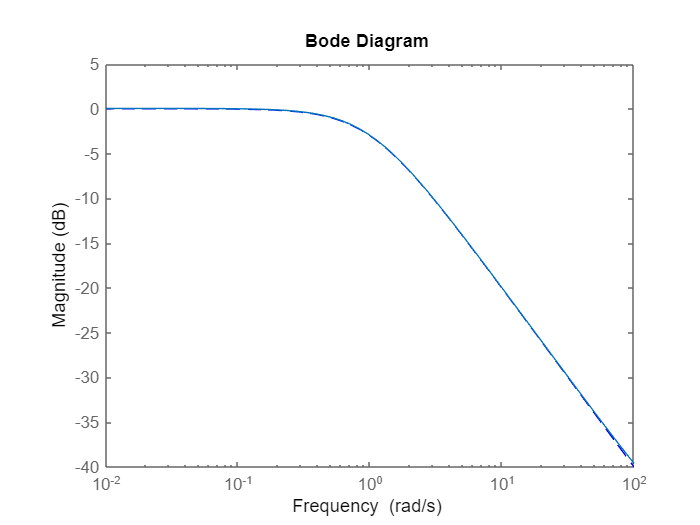


bodemag(G,'--', Gzi)